% Set the initial conditions and time range for the simulation
y01 = [0.01; 0.01];
y02 = [0.05; 0.05];
y03 = [0.1; 0.1];
tspan = [0 10];
% Solve the ODEs using ode45
[t, y1] = ode45(@Q2b1, tspan, y01);
[t, y2] = ode45(@Q2b1, tspan, y02);
[t, y3] = ode45(@Q2b1, tspan, y03);
% Extract the solution for v and u
v1 = y1(:,1);
u1 = y1(:,2);
v2 = y2(:,1);
u2 = y2(:,2);
v3 = y3(:,1);
u3 = y3(:,2);
% Plot the phase portrait
figure;
plot(v1, u1);
hold

已锁定最新绘图


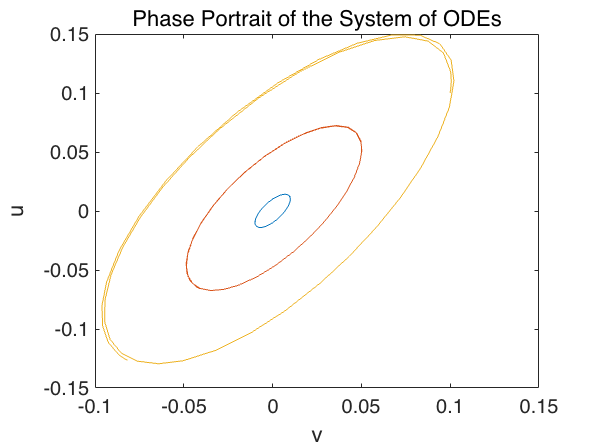

plot(v2, u2);
plot(v3, u3);
xlabel('v');
ylabel('u');
title('Phase Portrait of the System of ODEs');